%Vehiculo
% salida yaw rate entrada steering
% El control está diseñado para considerar una velocidad lineal entre 4 y 10 m/s (circuito urbano)
%Regulador diseñado en continuo con H_inf más agresivo
clear;
close all;

%System parameters
m=995;
a=1.233;
b=1.327;
Caf=41e3;
l=2.56;
Iz=1760;
Car=47e3;
g = 9.81;
%vx=6;%Regulador suave
%Vx=10;%Regulador agresivo
vx = ureal('vx',10,'Range',[4,10])

Uncertain real parameter "vx" with nominal value 7 and range [4,10].
Block Properties


a1=m*vx*a*Caf;
A1=m*a*Caf;
a2=l*Caf*Car;
A2=a2;
b1=m*vx*Iz;
B1=m*Iz;
b2=Iz*(Caf+Car)+m*((a^2)*Caf+(b^2)*Car);
B2=b2;
b3=(Caf*Car/vx)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
B3=(Caf*Car)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
s=tf('s');

p=(a1*s+a2)/(b1*s^2+b2*s+b3)%Proceso Continuo con incertidumbre

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 8 states.
The model uncertainty consists of the following blocks:
  vx: Uncertain real, nominal = 7, range = [4,10], 4 occurrences
Model Properties



%analisis
Planta=tf(p) %Planta nominal


Planta =
 
     28.72 s + 402.4
  ---------------------
  s^2 + 24.41 s + 148.3
 
Continuous-time transfer function.
Model Properties


disp('Polos:'),pole(Planta)

Polos:


ans =   -13.0494
  -11.3625


disp('Ceros:'),tzero(p)

Ceros:


ans = -14.0105


%Perido de muestreo
T=10e-3;%10ms
%load("paper2226.mat"); %Este regulador tiene un funcionamiento muy suave
K= 5.3897*(s+3.85)*(s+6)*(s+1.992)*(s+1.361)*(s^2 + 1.767*s + 1.422)/((s+11.29)*(s+1.354)*(s+0.001)*(s^2 + 0.9712*s + 0.239)*(s^2 + 9.127*s + 21.71))


K =
 
       5.39 s^6 + 80.68 s^5 + 450.5 s^4 + 1223 s^3 + 1780 s^2 + 1395 s + 480
  -------------------------------------------------------------------------------
  s^7 + 22.74 s^6 + 173.8 s^5 + 567.4 s^4 + 771 s^3 + 422 s^2 + 79.74 s + 0.07932
 
Continuous-time transfer function.
Model Properties


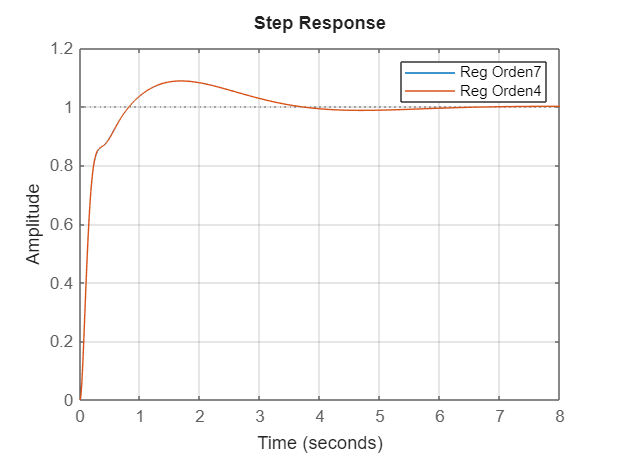

%       5.39 s^6 + 80.68 s^5 + 450.5 s^4 + 1223 s^3 + 1780 s^2 + 1394 s + 479.8
%  ----------------------------------------------------------------------------------
%  s^7 + 22.74 s^6 + 173.8 s^5 + 567.2 s^4 + 770.7 s^3 + 421.9 s^2 + 79.72 s + 0.0793
%Este regulador está diseñado para el modelo de coche de Berkeley, no para
%el modelo de Zang

%K: regulador continuo de orden 7
%Kred: regulador continuo de orden 4
Kred=balred(K,4);
BC1=minreal(K*Planta/(1+K*Planta));
BC2=minreal(Kred*Planta/(1+Kred*Planta));

figure,step(BC1,BC2),legend('Reg Orden7','Reg Orden4'),grid

%No hay diferencias apreciables

Gr=c2d(K,T,'zoh');
Reg=ss(Gr);
SR_Diag=canon(Reg,'modal') %No es diagonal, es triangular


SR_Diag =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1           1     -0.8703     -0.6914      0.7022     -0.6567      0.4946     -0.4225
   x2           0      0.9952        1.37      -1.371       1.237      -1.243       1.865
   x3           0  -2.375e-07      0.9952      -1.696       1.891      -2.503       3.308
   x4           0           0           0      0.9865       -2.44       3.102      -4.713
   x5           0           0           0           0      0.9553       -2.83       5.031
   x6           0           0           0           0   2.852e-05      0.9553       -4.04
   x7           0           0           0           0           0           0      0.8932
 
  B = 
            u1
   x1  0.06608
   x2  -0.1741
   x3   -0.331
   x4   0.4922
   x5  -0.5635
   x6   0.4873
   x7   -0.242
 
  C = 
               x1          x2          x3          x4          x5          x6          x7
   y1   2.825e-13  -3.954e-11  -

%No sirve la descomposición
% % eig(SR_Diag.A(1,1))
% % eig(SR_Diag.A(2:3,2:3))
% % eig(SR_Diag.A(4,4))
% % eig(SR_Diag.A(5:6,5:6))
% % eig(SR_Diag.A(7,7))
pole(Reg)

ans =    1.0003 + 0.0000i
   0.9951 + 0.0019i
   0.9951 - 0.0019i
   0.9863 + 0.0000i
   0.9554 + 0.0090i
   0.9554 - 0.0090i
   0.8932 + 0.0000i



%No es diagonalizable, produce T con imaginarios 
[V,Lambda] = eig(Reg.A);

% Comprobar que el sistema es diagonalizable (V invertible)
% if rcond(V) < 1e-10
%     error('La matriz A_d es (numéricamente) no diagonalizable');
% end

% Transformación de coordenadas: x = V * z  =>  z = V^{-1} x
Ti = inv(V);
A_diag = Ti*Reg.A*inv(T)      % ~ Lambda (diagonal) %

A_diag = 1.0e+14 *

   0.2635 + 0.0000i  -0.3809 - 0.0000i   0.4585 + 0.0000i  -0.2943 - 0.0000i   0.2125 + 0.0000i  -0.1636 - 0.0000i   0.1049 + 0.0000i
  -0.0258 + 0.7618i   0.0369 - 1.1018i  -0.0440 + 1.3278i   0.0280 - 0.8531i  -0.0200 + 0.6164i   0.0153 - 0.4750i  -0.0097 + 0.3049i
  -0.0258 - 0.7618i   0.0369 + 1.1018i  -0.0440 - 1.3278i   0.0280 + 0.8531i  -0.0200 - 0.6164i   0.0153 + 0.4750i  -0.0097 - 0.3049i
  -0.2219 - 0.0000i   0.3215 + 0.0000i  -0.3880 - 0.0000i   0.2496 + 0.0000i  -0.1806 - 0.0000i   0.1394 + 0.0000i  -0.0896 - 0.0000i
   0.0057 - 0.0055i  -0.0083 + 0.0080i   0.0101 - 0.0097i  -0.0065 + 0.0063i   0.0047 - 0.0046i  -0.0037 + 0.0036i   0.0024 - 0.0023i
   0.0057 + 0.0055i  -0.0083 - 0.0080i   0.0101 + 0.0097i  -0.0065 - 0.0063i   0.0047 + 0.0046i  -0.0037 - 0.0036i   0.0024 + 0.0023i
   0.0000 + 0.0000i  -0.0001 - 0.0000i   0.0001 + 0.0000i  -0.0001 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i


% B_diag = Ti*Bd;
% C_diag = Cd*T;
% D_diag = Dd;
%%%%%%%%%%%%%%%%%%%%%
G = tf(Gr);  % El paso de ss a tf cambian polos ¿?
[pole(Gr) pole(G)]

ans =    1.0003 + 0.0000i   1.0003 + 0.0000i
   0.9951 + 0.0019i   0.9951 + 0.0019i
   0.9951 - 0.0019i   0.9951 - 0.0019i
   0.9863 + 0.0000i   0.9863 + 0.0000i
   0.9554 + 0.0090i   0.9554 + 0.0090i
   0.9554 - 0.0090i   0.9554 - 0.0090i
   0.8932 + 0.0000i   0.8932 + 0.0000i


[num den]=tfdata(G,'v');
[r, p, k] = residue(num, den)

r =    0.0482 + 0.0000i
  -0.0174 + 0.0216i
  -0.0174 - 0.0216i
   0.0001 + 0.0000i
   0.0025 + 0.0033i
   0.0025 - 0.0033i
   0.0334 + 0.0000i


p =    1.0003 + 0.0000i
   0.9951 + 0.0019i
   0.9951 - 0.0019i
   0.9863 + 0.0000i
   0.9554 + 0.0090i
   0.9554 - 0.0090i
   0.8932 + 0.0000i



k =

     []



% Mostrar en pantalla
disp('Descomposición en fracciones simples:');

Descomposición en fracciones simples:


if ~isempty(k)
    fprintf('Término directo: %s\n', num2str(k));
end
for i = 1:length(r)
    if imag(r(i))==0
     fprintf('R%d/(z - P%d) = %.4f / (z - %.4f)\n', i, i, r(i), p(i));
    else
     fprintf('R%d/(z - P%d) = (%.4f+%.4f i) / (z - (%.4f+%.4f i))\n', i, i, real(r(i)),imag(r(i)), real(p(i)),imag(p(i)));
    end
end

R1/(z - P1) = 0.0482 / (z - 1.0003)


R2/(z - P2) = (-0.0174+0.0216 i) / (z - (0.9951+0.0019 i))
R3/(z - P3) = (-0.0174+-0.0216 i) / (z - (0.9951+-0.0019 i))


R4/(z - P4) = 0.0001 / (z - 0.9863)


R5/(z - P5) = (0.0025+0.0033 i) / (z - (0.9554+0.0090 i))
R6/(z - P6) = (0.0025+-0.0033 i) / (z - (0.9554+-0.0090 i))


R7/(z - P7) = 0.0334 / (z - 0.8932)


%Falfa juntar polos complejos
%[Reg_sep np]=regdiagSISOsep(G) %No funciona bien
[num den]=tfdata(Reg,'v');
[r p k]=residue(num,den)

r =    0.0496 + 0.0000i
  -0.0181 + 0.0247i
  -0.0181 - 0.0247i
   0.0000 + 0.0000i
   0.0025 + 0.0033i
   0.0025 - 0.0033i
   0.0334 + 0.0000i


p =    1.0003 + 0.0000i
   0.9951 + 0.0018i
   0.9951 - 0.0018i
   0.9863 + 0.0000i
   0.9554 + 0.0090i
   0.9554 - 0.0090i
   0.8932 + 0.0000i



k =

     []



S1=ss(tf(r(1),[1 -p(1)],T))


S1 =
 
  A = 
       x1
   x1   1
 
  B = 
         u1
   x1  0.25
 
  C = 
           x1
   y1  0.1986
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.
Model Properties


n2=real([r(2)+r(3) -r(2)*p(3)-r(3)*p(2)])

n2 =    -0.0363    0.0360


d2=real([1 -(p(2)+p(3)) p(2)*p(3)])

d2 =     1.0000   -1.9902    0.9903


S2= canon(tf(n2, d2,T),'modal')


S2 =
 
  A = 
              x1         x2
   x1     0.9951   0.001807
   x2  -0.001807     0.9951
 
  B = 
               u1
   x1      0.1772
   x2  -0.0001601
 
  C = 
            x1       x2
   y1  -0.2046   0.2794
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


S3=ss(tf(r(4),[1 -p(4)],T))


S3 =
 
  A = 
           x1
   x1  0.9863
 
  B = 
             u1
   x1  0.007812
 
  C = 
             x1
   y1  0.004817
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.
Model Properties


n4=real([r(5)+r(6) -r(5)*p(6)-r(6)*p(5)])

n4 =     0.0051   -0.0049


d4=real([1 -(p(5)+p(6)) p(5)*p(6)])

d4 =     1.0000   -1.9107    0.9128


S4= canon(tf(n4, d4,T),'modal')


S4 =
 
  A = 
             x1        x2
   x1    0.9554   0.00898
   x2  -0.00898    0.9554
 
  B = 
               u1
   x1     0.09038
   x2  -0.0004054
 
  C = 
            x1       x2
   y1  0.05663  0.07365
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


S5=ss(tf(r(7),[1 -p(7)],T))


S5 =
 
  A = 
           x1
   x1  0.8932
 
  B = 
         u1
   x1  0.25
 
  C = 
           x1
   y1  0.1336
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.
Model Properties


[abs(pole(S1)); abs(pole(S2)); abs(pole(S3)); abs(pole(S4)); abs(pole(S5))]

ans =     1.0003
    0.9951
    0.9951
    0.9863
    0.9554
    0.9554
    0.8932



[dcgain(S1) dcgain(S2) dcgain(S3) dcgain(S4) dcgain(S5)]

ans =  -181.0213   -9.8313    0.0028    0.0806    0.3128


%%%%%%%%%%%%%%%%%%%%%


%Hay 5 dinámicas: 3 simples + 2 complejas

[pole(SR_Diag) abs(pole(SR_Diag))]

ans =    1.0000 + 0.0000i   1.0000 + 0.0000i
   0.9952 + 0.0006i   0.9952 + 0.0000i
   0.9952 - 0.0006i   0.9952 + 0.0000i
   0.9865 + 0.0000i   0.9865 + 0.0000i
   0.9553 + 0.0090i   0.9554 + 0.0000i
   0.9553 - 0.0090i   0.9554 + 0.0000i
   0.8932 + 0.0000i   0.8932 + 0.0000i


%Ordenador polos de mayor a menor rapidez
p1=pole(S1);%Real
p2p3=pole(S2);%Complejo
p4=pole(S3);%Real
p5p6=pole(S4);%Complejo
p7=pole(S5);%Real

%Analisis de las 10 dinamicas
disp('[polo abs c*b ganancia]')

[polo abs c*b ganancia]


comp=[p1 abs(p1) norm(S1.C*S1.B) dcgain(S1)
 p2p3(1) abs(p2p3(1)) norm(S2.C*S2.B) dcgain(S2)
 p4 abs(p4) norm(S3.C*S3.B) dcgain(S3)
 p5p6(1) abs(p5p6(1)) norm(S4.C*S4.B(1,:)) dcgain(S4)
 p7 abs(p7) norm(S5.C*S5.B) dcgain(S5)]

comp = 1.0e+02 *

   0.0100 + 0.0000i   0.0100 + 0.0000i   0.0005 + 0.0000i  -1.8102 + 0.0000i
   0.0100 + 0.0000i   0.0100 + 0.0000i   0.0004 + 0.0000i  -0.0983 + 0.0000i
   0.0099 + 0.0000i   0.0099 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0096 + 0.0001i   0.0096 + 0.0000i   0.0001 + 0.0000i   0.0008 + 0.0000i
   0.0089 + 0.0000i   0.0089 + 0.0000i   0.0003 + 0.0000i   0.0031 + 0.0000i



%Ordenados por rapidez
%[p7 p5p6 p4 p2p3 p1]
%Ordenados por ganancia (c*b) residuo
%[p1 p2p3 p7 p5p6 p4]
%Analisis modelo balanceado
[SR_Bal gr]=balreal(Gr)


SR_Bal =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1           1  -1.664e-05   1.196e-05   9.007e-06   1.131e-06   1.746e-07  -1.426e-08
   x2   1.664e-05       0.997    0.004455    0.003255   0.0004022   6.207e-05  -5.071e-06
   x3   1.196e-05   -0.004455       0.962    -0.04359     -0.0075   -0.001167   9.519e-05
   x4   9.007e-06   -0.003255    -0.04359       0.933    -0.01746   -0.002755   0.0002241
   x5   1.131e-06  -0.0004022     -0.0075    -0.01746      0.9156    -0.03479    0.002217
   x6  -1.746e-07   6.207e-05    0.001167    0.002755     0.03479      0.9872    0.001987
   x7   1.426e-08  -5.071e-06  -9.519e-05  -0.0002241   -0.002217    0.001987       0.986
 
  B = 
              u1
   x1    -0.2451
   x2     0.2126
   x3     0.1533
   x4     0.1154
   x5    0.01449
   x6  -0.002237
   x7  0.0001827
 
  C = 
               x1          x2          x3          x4          x5          x6          x7
   y1     -0.2451

gr = 1.0e+03 *

    3.1401
    0.0076
    0.0003
    0.0001
    0.0000
    0.0000
    0.0000


disp('[polo gan]')

[polo gan]


[pole(SR_Bal) gr]

ans = 1.0e+03 *

   0.0009 + 0.0000i   3.1401 + 0.0000i
   0.0010 + 0.0000i   0.0076 + 0.0000i
   0.0010 - 0.0000i   0.0003 + 0.0000i
   0.0010 + 0.0000i   0.0001 + 0.0000i
   0.0010 + 0.0000i   0.0000 + 0.0000i
   0.0010 - 0.0000i   0.0000 + 0.0000i
   0.0010 + 0.0000i   0.0000 + 0.0000i


%Ordenados por gr (gramiano)
%[p7 p2p3 p1 p5p6 p4]
 

%Prueba para N=4
N=4;
GrN4=d2d(Gr,T*N);%Discreto a periodo 4T mucho error de posición
GrN3=d2d(Gr,T*3);%Discreto a periodo 3T un poco error de posición
GrN2=d2d(Gr,T*2);%Discreto a periodo 2T error posición inapreciable

%Forma diagonal
nr=1;%1 reales
nl=[1 2 1 2];%(1reales o 2complejos)
%Reduce el orden de 7 a 2-3
RegDiag_Rap=S5;
RegDiag_Len1=S1;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=S2;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=S3


RegDiag_Len3 =
 
  A = 
           x1
   x1  0.9863
 
  B = 
             u1
   x1  0.007812
 
  C = 
             x1
   y1  0.004817
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.
Model Propert

RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);
RegDiag_Len4=S4;
RegDiag_Len4_ext=d2d(RegDiag_Len4,N*T);



%Forma balanceada
[RegBal_sep]=regsep(SR_Bal,[nr nl]);%[nr nl1 nl2 nl3 nl4]
RegBal_Rap=RegBal_sep.S1;
RegBal_Len1=RegBal_sep.S2;
RegBal_Len1_ext=d2d(RegBal_Len1,N*T);
RegBal_Len2=RegBal_sep.S3;
RegBal_Len2_ext=d2d(RegBal_Len2,N*T);
RegBal_Len3=RegBal_sep.S4;
RegBal_Len3_ext=d2d(RegBal_Len3,N*T);
RegBal_Len4=RegBal_sep.S5;
RegBal_Len4_ext=d2d(RegBal_Len4,N*T);
%nrr=nr,nl1=nl(1),nl2=nl(2),nl3=nl(3);

sim('PruebaN4');

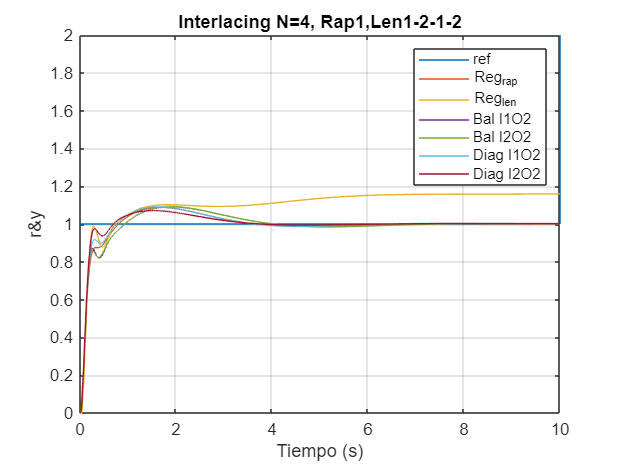

f=figure;
set(f,'Name','Interlacing N=4, Rap1,Len1-2-1-2')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=4, Rap1,Len1-2-1-2');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')

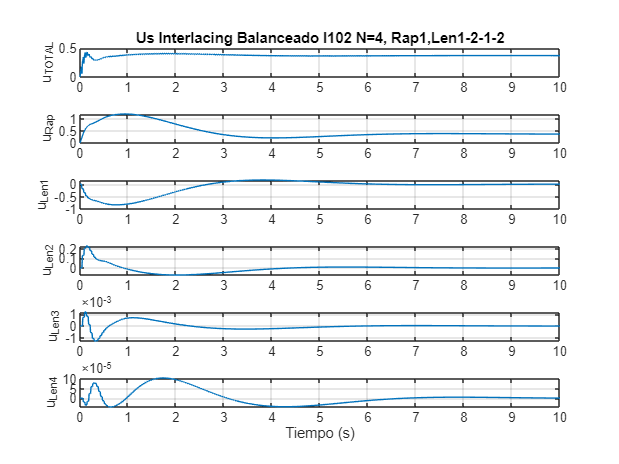

Y_A.time=datos.time;
Y_A.values=datos.signals.values(:,7);

f=figure;
set(f,'Name','U Interlacing Balanceado I102 N=4, Rap1,Len1-2-1-2')
subplot(611),plot(Us.time,Us.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing Balanceado I102 N=4, Rap1,Len1-2-1-2');
subplot(612),plot(Us.time,Us.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(613),plot(Us.time,Us.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(614),plot(Us.time,Us.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(615),plot(Us.time,Us.signals(5).values),ylabel('u_{Len3}'),grid;
subplot(616),plot(Us.time,Us.signals(6).values),ylabel('u_{Len4}'),grid;
xlabel('Tiempo (s)'),

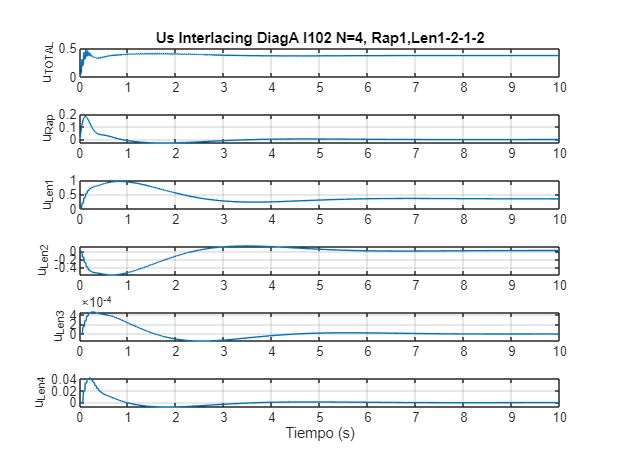

f=figure;
set(f,'Name','U Interlacing DiagA I102 N=4, Rap1,Len1-2-1-2')
subplot(611),plot(UsDiag.time,UsDiag.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing DiagA I102 N=4, Rap1,Len1-2-1-2');
subplot(612),plot(UsDiag.time,UsDiag.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(613),plot(UsDiag.time,UsDiag.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(614),plot(UsDiag.time,UsDiag.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(615),plot(UsDiag.time,UsDiag.signals(5).values),ylabel('u_{Len3}'),grid;
subplot(616),plot(UsDiag.time,UsDiag.signals(6).values),ylabel('u_{Len4}'),grid;
xlabel('Tiempo (s)'),



%Cambiamos el orden de los subsistemas diagonales
%Ordenados por gr (gramiano)
%[p7 p2p3 p1 p5p6 p4]
RegDiag_Rap=S5;
RegDiag_Len1=S2;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=S1;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=S4


RegDiag_Len3 =
 
  A = 
             x1        x2
   x1    0.9554   0.00898
   x2  -0.00898    0.9554
 
  B = 
               u1
   x1     0.09038
   x2  -0.0004054
 
  C = 
            x1       x2
   y1  0.05663  0.07365
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);
RegDiag_Len4=S3;
RegDiag_Len4_ext=d2d(RegDiag_Len4,N*T);

sim('PruebaN4');

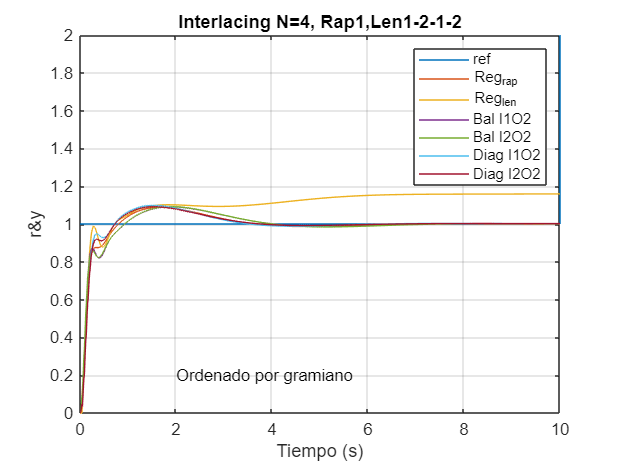

f=figure;
set(f,'Name','Interlacing N=4, Rap1,Len1-2-1-2')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=4, Rap1,Len1-2-1-2');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')
text(2,0.2,'Ordenado por gramiano')

%No hay diferencia apreciable, quizás no sube tan deprisa por 
Y_B.time=datos.time;
Y_B.values=datos.signals.values(:,7);

%Cambiamos el orden de los subsistemas diagonales
%Ordenados por rapidez (modulo polo)
%[p7 p2p3 p1 p5p6 p4]
RegDiag_Rap=S5;
RegDiag_Len1=S4;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=S3;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=S2


RegDiag_Len3 =
 
  A = 
              x1         x2
   x1     0.9951   0.001807
   x2  -0.001807     0.9951
 
  B = 
               u1
   x1      0.1772
   x2  -0.0001601
 
  C = 
            x1       x2
   y1  -0.2046   0.2794
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);
RegDiag_Len4=S1;
RegDiag_Len4_ext=d2d(RegDiag_Len4,N*T);

sim('PruebaN4');

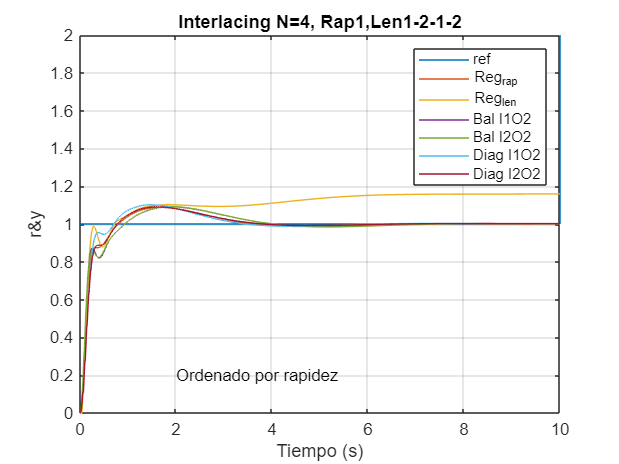

f=figure;
set(f,'Name','Interlacing N=4, Rap1,Len1-2-1-2')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=4, Rap1,Len1-2-1-2');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')
text(2,0.2,'Ordenado por rapidez')

%No hay diferencia apreciable, quizás no sube tan deprisa por 
Y_C.time=datos.time;
Y_C.values=datos.signals.values(:,7);

%Cambiamos el orden de los subsistemas diagonales
%Ordenados por rapidez al reves (modulo polo)
%[p7 p2p3 p1 p5p6 p4]
RegDiag_Rap=S1;
RegDiag_Len1=S2;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=S3;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=S4


RegDiag_Len3 =
 
  A = 
             x1        x2
   x1    0.9554   0.00898
   x2  -0.00898    0.9554
 
  B = 
               u1
   x1     0.09038
   x2  -0.0004054
 
  C = 
            x1       x2
   y1  0.05663  0.07365
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.


RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);
RegDiag_Len4=S5;
RegDiag_Len4_ext=d2d(RegDiag_Len4,N*T);

sim('PruebaN4');

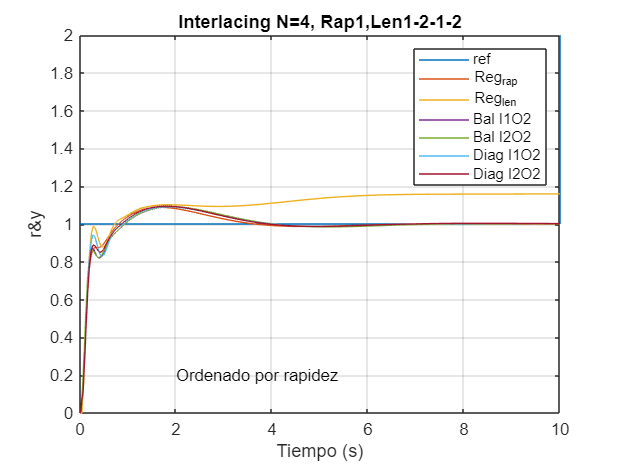

f=figure;
set(f,'Name','Interlacing N=4, Rap1,Len1-2-1-2')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=4, Rap1,Len1-2-1-2');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')
text(2,0.2,'Ordenado por rapidez')

%No hay diferencia apreciable, quizás no sube tan deprisa por 
Y_D.time=datos.time;
Y_D.values=datos.signals.values(:,7);


f=figure

f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


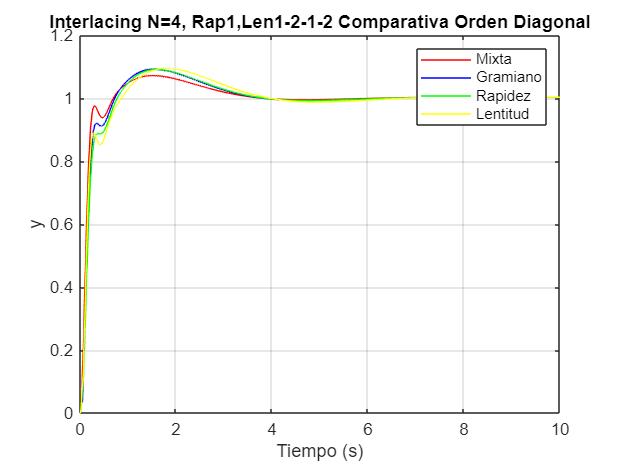

set(f,'Name','Interlacing N=4, Rap1,Len1-2-1-2 Comparativa Orden Diagonal')
plot(Y_A.time,Y_A.values,'r'),ylabel('y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=4, Rap1,Len1-2-1-2 Comparativa Orden Diagonal');
hold on;
plot(Y_B.time,Y_B.values, 'b')
plot(Y_C.time,Y_C.values, 'g')
plot(Y_D.time,Y_D.values, 'y')
legend('Mixta','Gramiano','Rapidez', 'Lentitud')

%Las 3 primeras opciones tienen la más rápida en la parte rápida
